% Definisco i parametri caratteristici
M = 1.7;
m = 0.7;
L = 0.7;
g = 9.81;

% Matrici
A = [0, 1, 0, 0;
     0, 0, -m*g/M, 0;
     0, 0, 0, 1;
     0, 0, (M+m)*g/(M*L), 0]

A =          0    1.0000         0         0
         0         0   -4.0394         0
         0         0         0    1.0000
         0         0   19.7849         0



B = [0; 1/M; 0; -1/(M*L)]

B =          0
    0.5882
         0
   -0.8403



C = [1, 0, 0, 0;
     0, 0, 1, 0]

C =      1     0     0     0
     0     0     1     0



D = [0; 0]

D =      0
     0


% Definizione del sistema in forma di stato
sys = ss(A,B,C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -4.039       0
   x3       0       0       0       1
   x4       0       0   19.78       0
 
  B = 
            u1
   x1        0
   x2   0.5882
   x3        0
   x4  -0.8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.




% autovalori
eig(A)

ans =          0
         0
    4.4480
   -4.4480


% Controllabilità ed Osservabilità
if(rank(ctrb(A,B)) == length(A))
    disp("il sistema è completamente controllabile");
else
    disp("il sistema non è completamente controllabile");
end

il sistema è completamente controllabile


 
if(rank(obsv(A,C)) == length(A))
    disp("il sistema è completamente osservabile");
else
    disp("il sistema non è completamente osservabile");
end

il sistema è completamente osservabile


% Retroazione di stato con controllore LQR
Q = C'*C;
%R = 1/50; % usato da Nicolas
R = 10; % usato nelle slide secondo Gemini
[K,S,CLP]=lqr(sys,Q,R);


% sistema in anello chiuso con retroazione K
sys_cl = ss(A-B*K,B,C,D)

sys_cl =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2    0.186   0.8094    27.08    7.154
   x3        0        0        0        1
   x4  -0.2657   -1.156   -24.68   -10.22
 
  B = 
            u1
   x1        0
   x2   0.5882
   x3        0
   x4  -0.8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% Calcolo la risposta libera
x0 = [-0.5; -0.3; 0.3; 0.5]

x0 =    -0.5000
   -0.3000
    0.3000
    0.5000


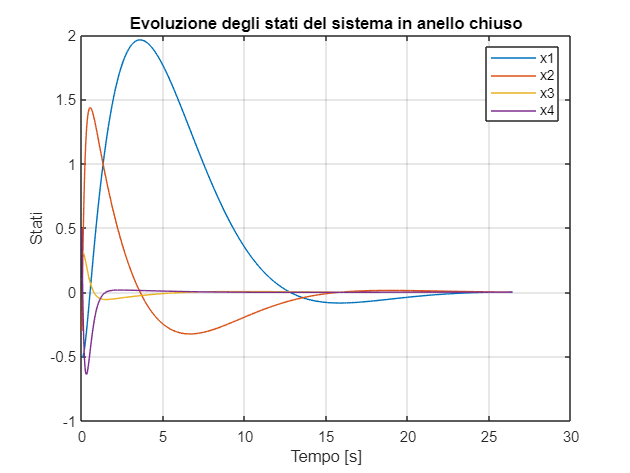


[Y, T, X] = initial(sys_cl, x0);

%t = 0:0.01:15; %vettore dei tempi (intervallo di tempo per la simulazione)
%[Y, T, X] = initial(sys_cl, x0, t);


% visualizzare gli stati e le uscite del sistema
figure;
 plot(T,X);
 legend("x1", "x2", "x3", "x4");
 xlabel("Tempo [s]");
 ylabel("Stati");
 title("Evoluzione degli stati del sistema in anello chiuso");
 grid on;

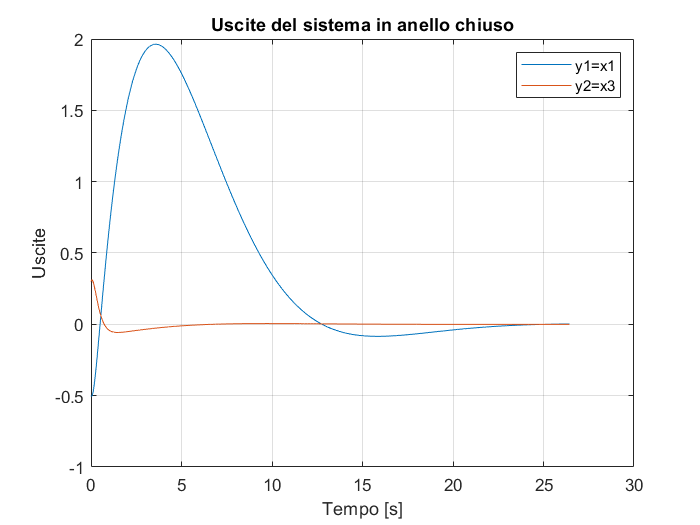


 figure;
 plot(T,Y);
 legend("y1=x1", "y2=x3");
 xlabel("Tempo [s]");
 ylabel("Uscite");
 title("Uscite del sistema in anello chiuso");
 grid on;